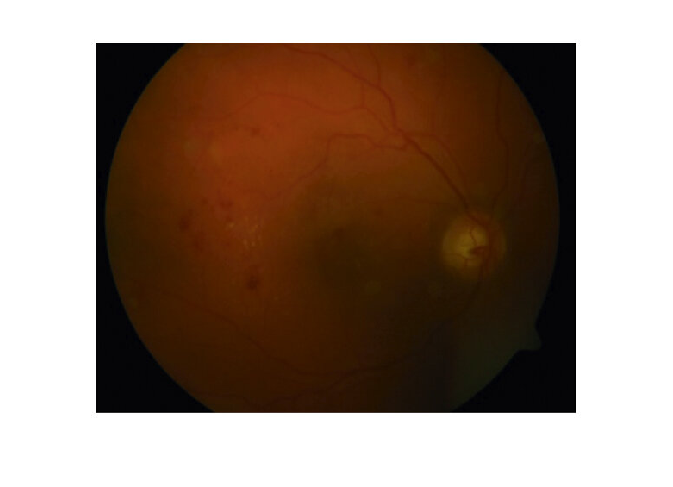

%% Homormophic filtering
I=imread("retina.png");
imshow(I)

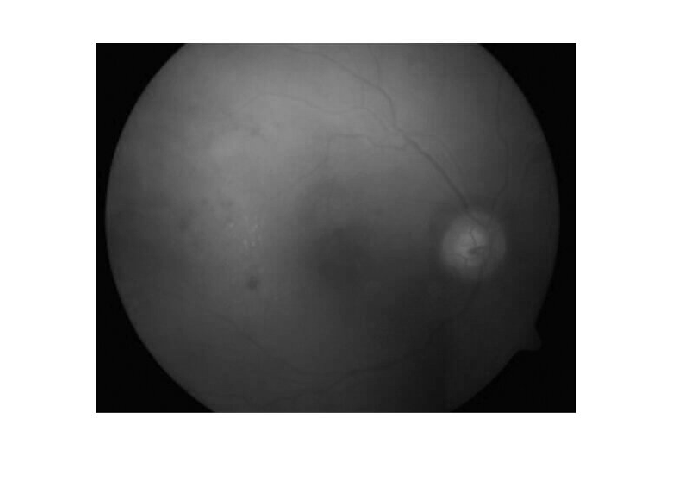

Idouble = double(I(:,:,1))/255;
imshow(Idouble);

## Filtering

Ilog = log(Idouble.*1000 + 10*ones(size(Idouble)) );
subplot(121)
imshow(Idouble,[]);
sharp = [-1, -1, -1; -1, 10, -1; -1, -1, -1]/2

sharp =    -0.5000   -0.5000   -0.5000
   -0.5000    5.0000   -0.5000
   -0.5000   -0.5000   -0.5000


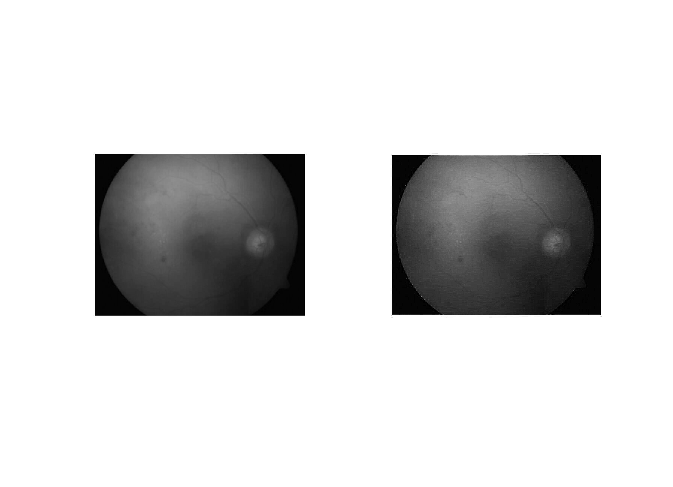

Isharp = conv2(Ilog,sharp,"same");
Isharp = exp(Isharp) - 10*ones(size(Isharp));
subplot(122)
imshow(Isharp,[0,1000]);

## With function

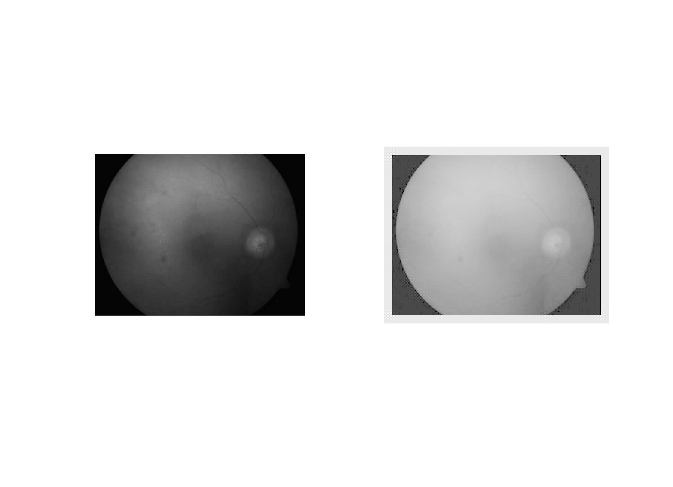

im=Idouble.*255;
imshow(im,[])
[r c]=size(im);
d=10;
order=2;
homofil(im,d,r,c,order);

## Check sharpening freq

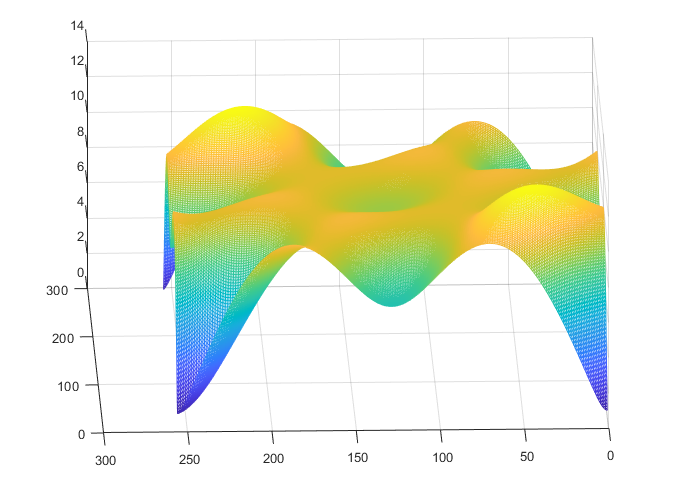

SH = fft2(fftshift(sharp),256,256);
subplot(1,1,1);
mesh(abs(SH))